# Fast Fourier Transform

#### Data: Signal from LIGO detector

file = readtable('Quiz3DataFile.csv');

$$equ = -L^{3}+4\,L^{2}-4\,L=0$$

$$eigenvalues = \left(\begin{array}{c} 0\\ 2\\ 2 \end{array}\right)$$

$$e\_1 = \left(\begin{array}{c} w_{x}+w_{z}=0\\ 2\,w_{y}=0\\ w_{x}+w_{z}=0 \end{array}\right)$$

$$e\_2 = \left(\begin{array}{c} w_{z}-w_{x}=0\\ 0=0\\ w_{x}-w_{z}=0 \end{array}\right)$$

$$e\_3 = \left(\begin{array}{c} w_{z}-w_{x}=0\\ 0=0\\ w_{x}-w_{z}=0 \end{array}\right)$$

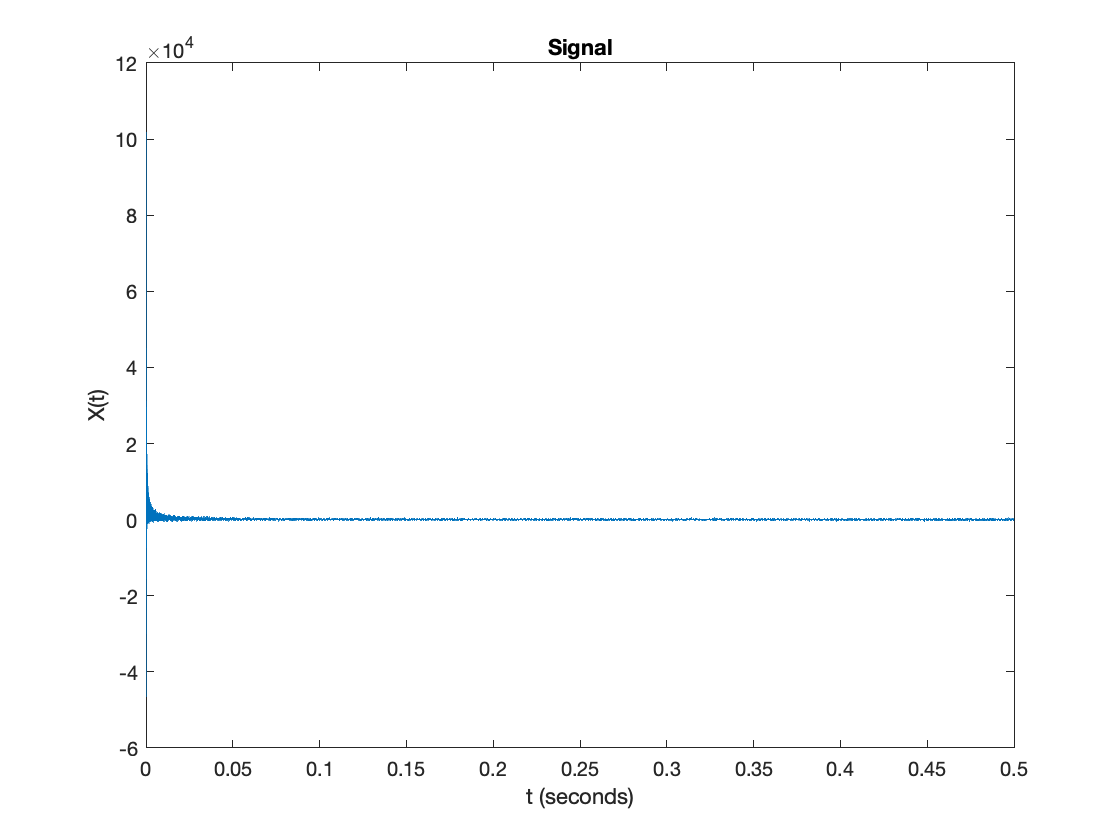

t = file{:,1}; % time (seconds)
X = file{:,2}; % detected signal
plot(t,X)
title('Signal')
xlabel('t (seconds)')
ylabel('X(t)')

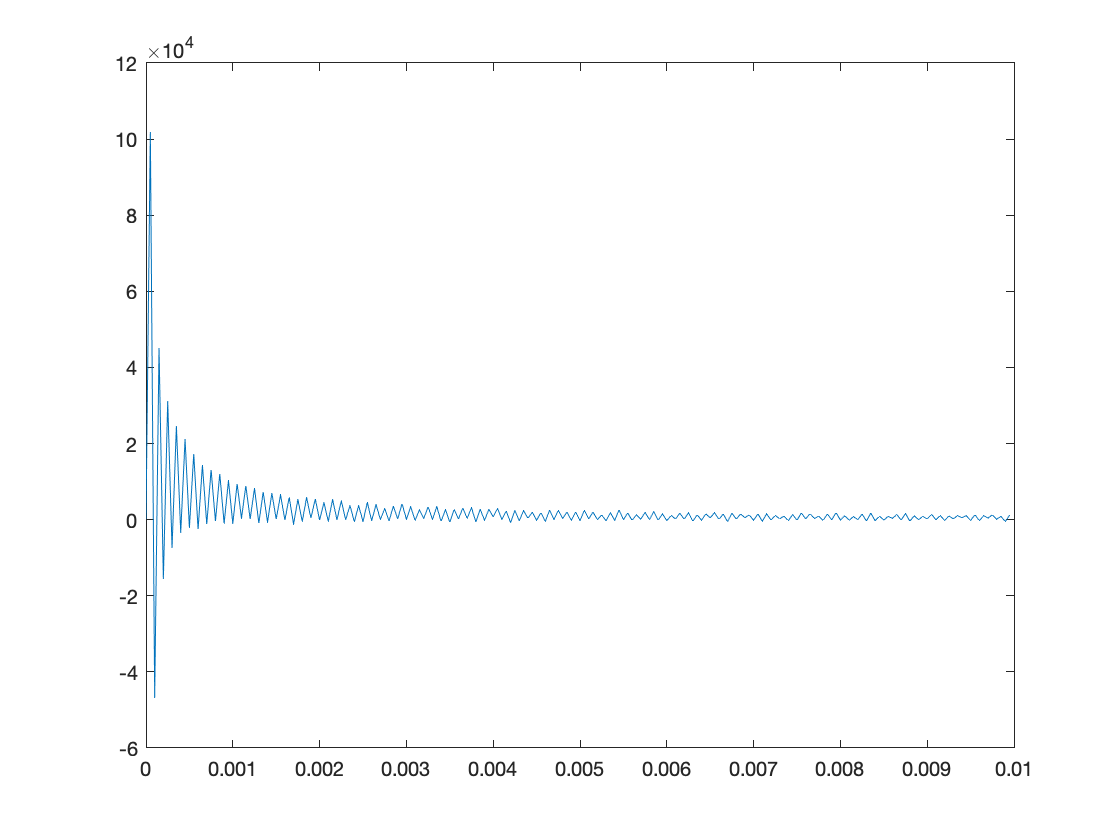


plot(t(1:200), X(1:200))

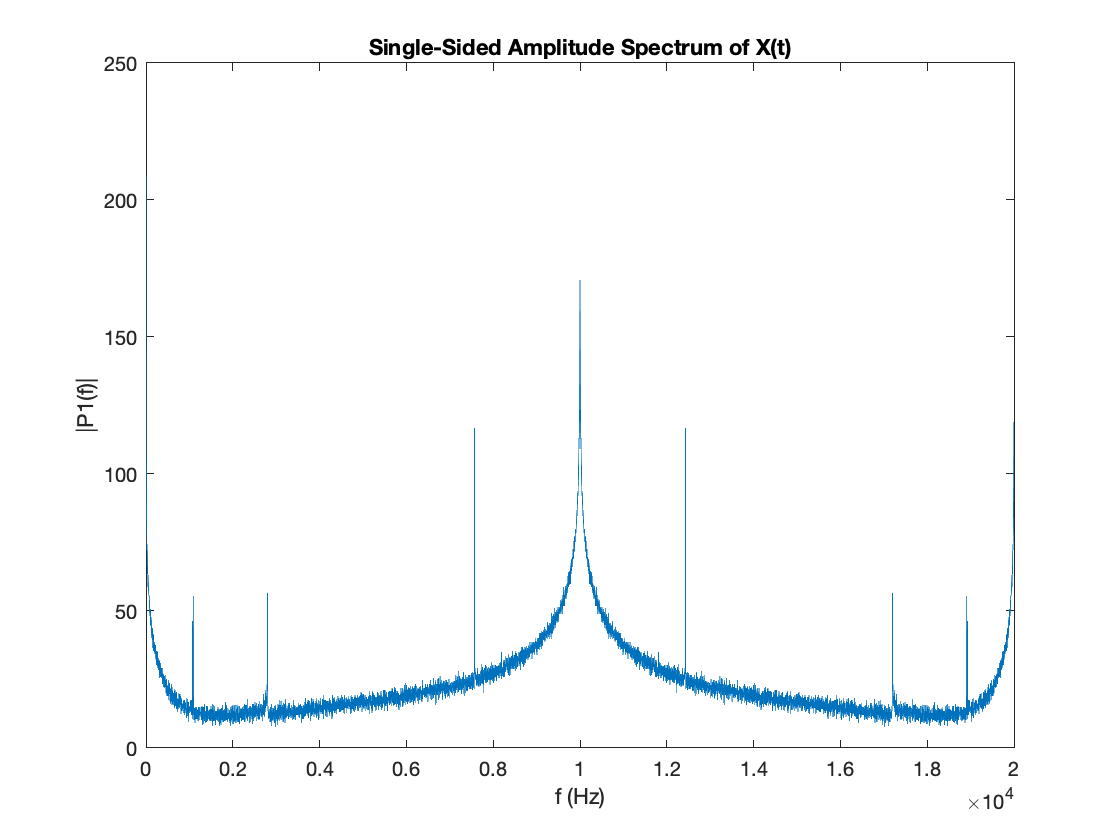


% Large signal from 0 to 0.001 seconds, then tapers off

Fs = 20000; % Sampling frequency 
% should be twice the frequency of the signal
% period looks to be around 0.0001 seconds
% so frequency of around 10000 Hz
% so sampling frequency of 20000 Hz
L = size(X,1); % Data length (Length of signal)

Y = fft(X); % Fourier Transform
P = abs(Y*2/L); % Realize and Normalize
f = Fs*(0:L-1)/L; % Make bin widths

% FFT produces characteristic frequencies and their
% mirror image

plot(f(1:10000), P(1:10000)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

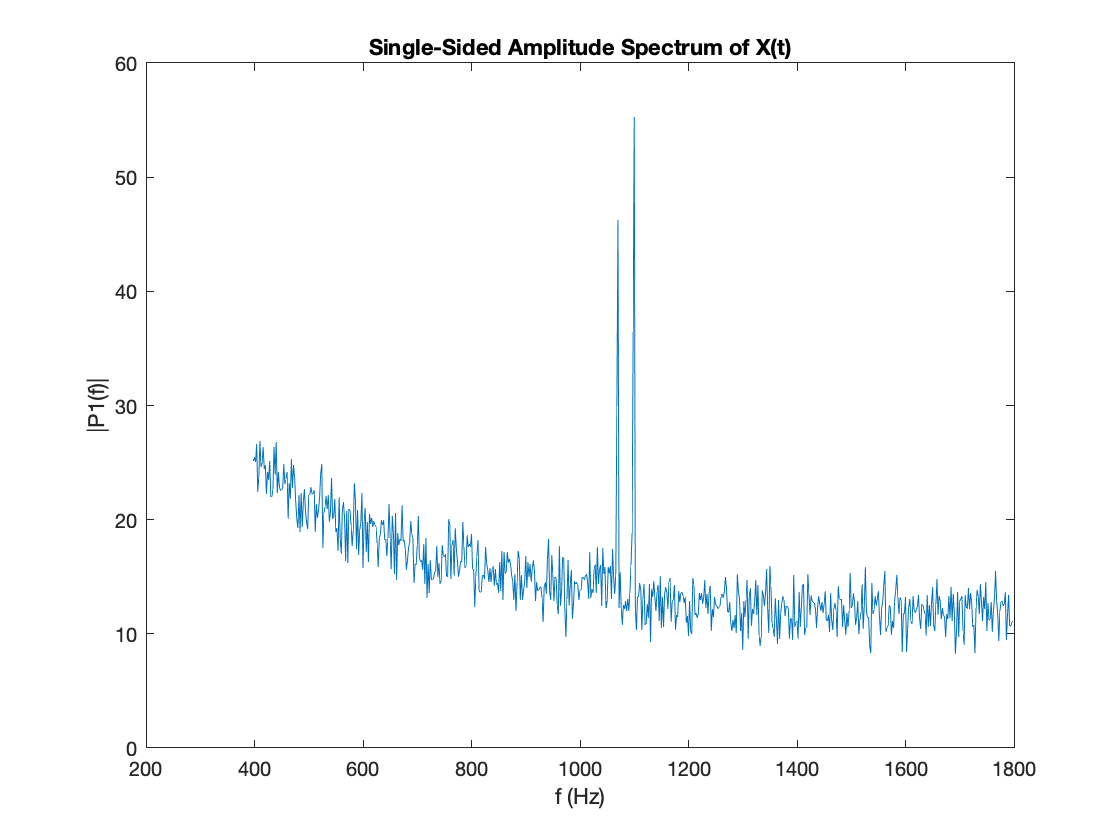


% The spike in the middle represents the large
% signal at first few milliseconds, everything 
% after is a reflection
% three characteristic frequencies below spike

% difficult to tell if this large spike in the middle is 
% 'characteristic'

% First characteristic frequency is actually two seperate frequencies
plot(f(200:900), P(200:900)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

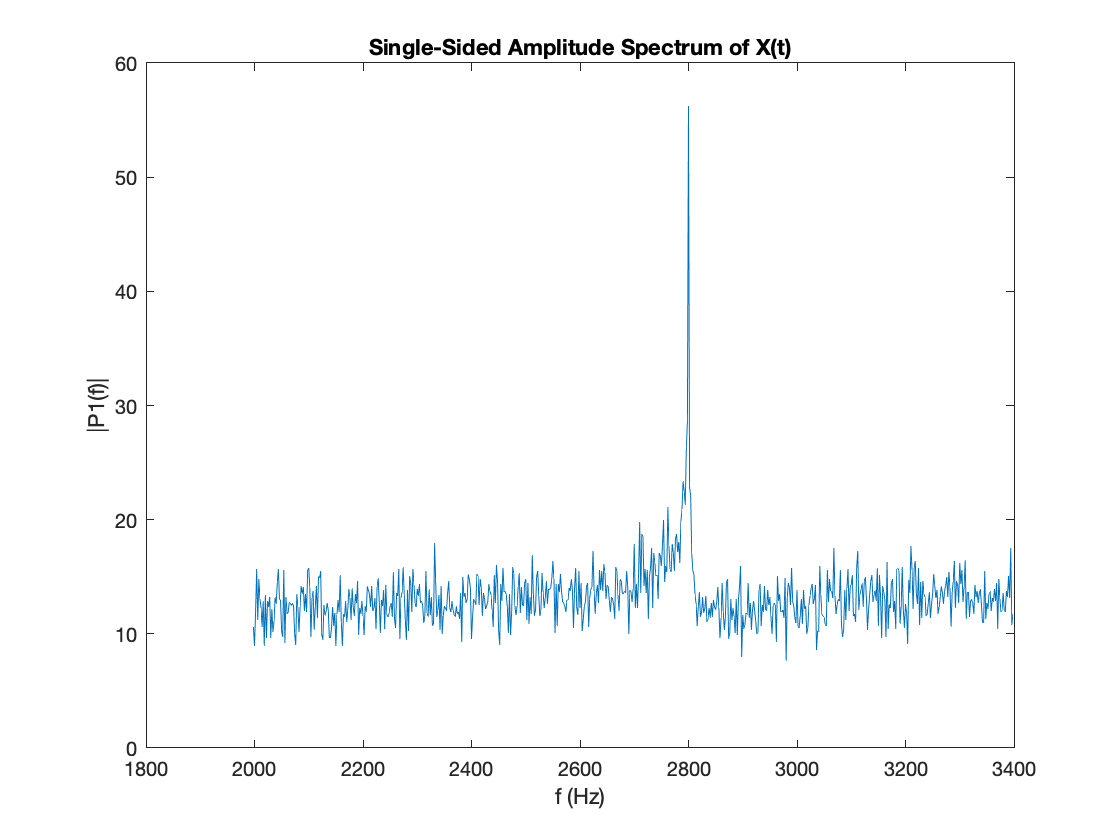

% First two characteristic frequencies are
% 1070 Hz, 1110 Hz 

plot(f(1000:1700), P(1000:1700)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

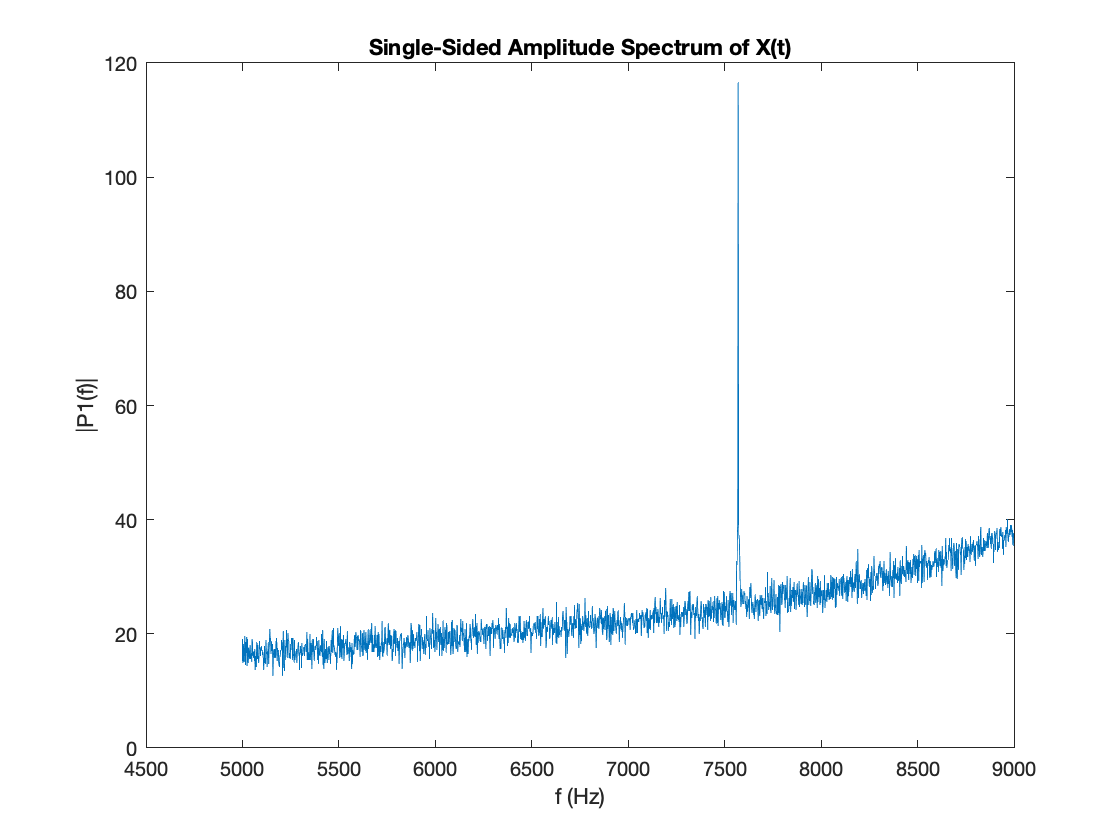

% Third characteristic freauency
% 2798 Hz

plot(f(2500:4500), P(2500:4500)) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)') 
ylabel('|P1(f)|')

% Fourth char freq
% 7572 Hz